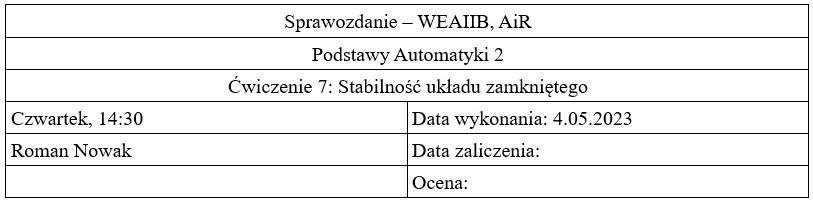

Celem ćwiczenia jest zapoznanie się z badaniem stabilności zamkniętego układu regulacji automatycznej z wykorzystaniem: kryterium Nyquista oraz kryterium Hurwitza. Rozważmy zamknięty układ regulacji składający się z obiektu Go o transmitancji podanej we wzorze 1 i regulatora PID o transmitancji (2)

                                                                                       (1)

                                                                                    (2)

Należy dobrać parametry regulatora tak, by układ był stabilny, sprawdzająć efekty zmian parametrów za pomocą kreteriów stabilności Nyqusta i Hurwitza

Kryterium Nyquista bada stabilność układu zamkniętego ujemnym sprzężeniem zwrotnym, na podstawie charakterystyki Nyquista układu otwartego - jeśli nie obejmuje ona punktu (-1, 0j), to układ zamknięty jest stabilny.

Kryterium Hurwitza, polega na stworzeniu macierzy Hurwitza z równania charakterystycznego układu (mianownika transmitancji). Układ jest stabilny jeśli macierz Hurwitza jest dodatnio określona - minory główne większe od 0.

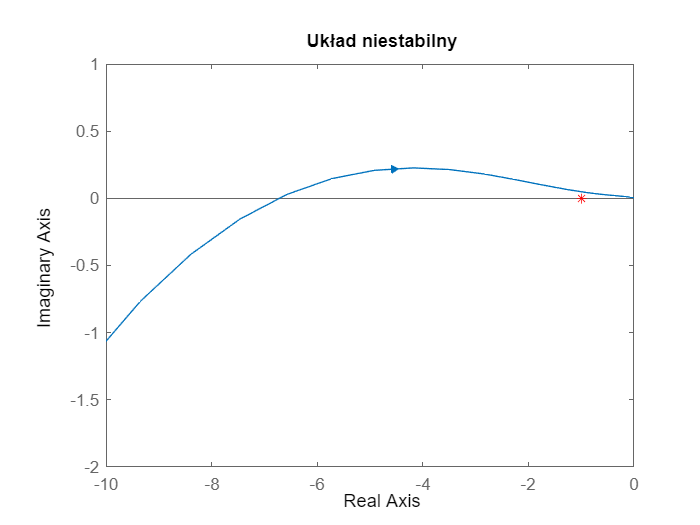

clear;

k = 2 ; Ti = 1 ; Td = 0.5;
G = nyquist_stab(k, Ti, Td);
axis([-10 0 -2 1]);
title("Układ niestabilny");

Sprawdzam za pomocą kryterium Hurwitza

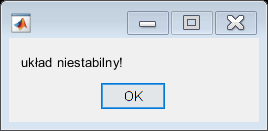

G = hurwitz(k, Ti, Td);

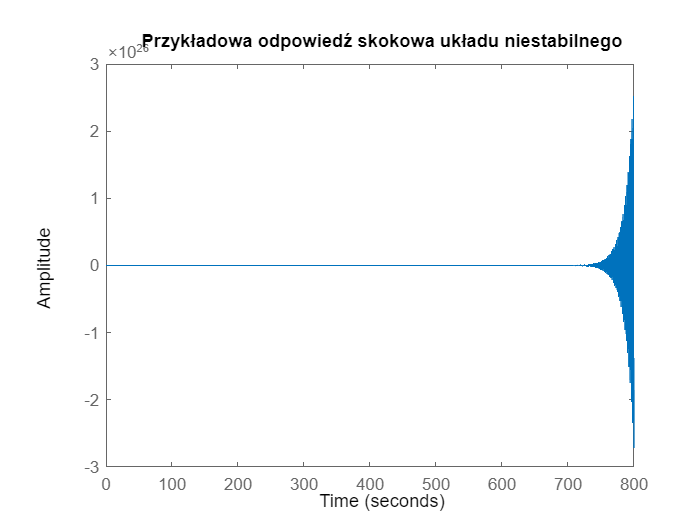

figure; step(G); title("Przykładowa odpowiedź skokowa układu niestabilnego");

Zmniejszam k, żeby wykres Nyquista nie obejmował punktu (0, -1)

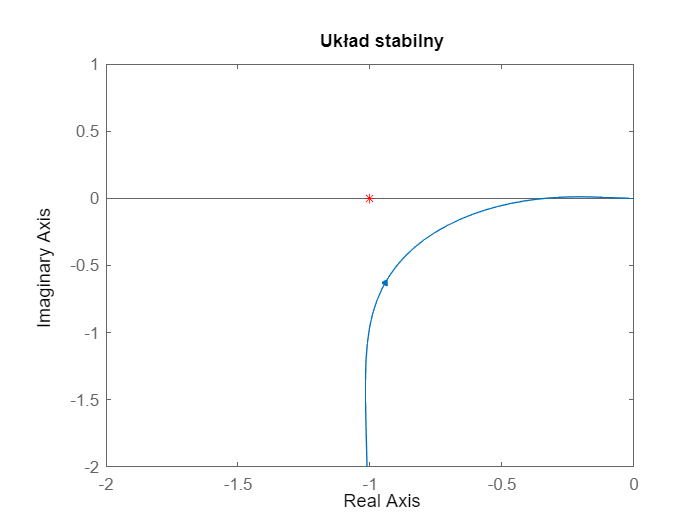

k = 0.1 ; Ti = 1 ; Td = 0.5;
G = nyquist_stab(k, Ti, Td);
axis([-2 0 -2 1]);
title("Układ stabilny");

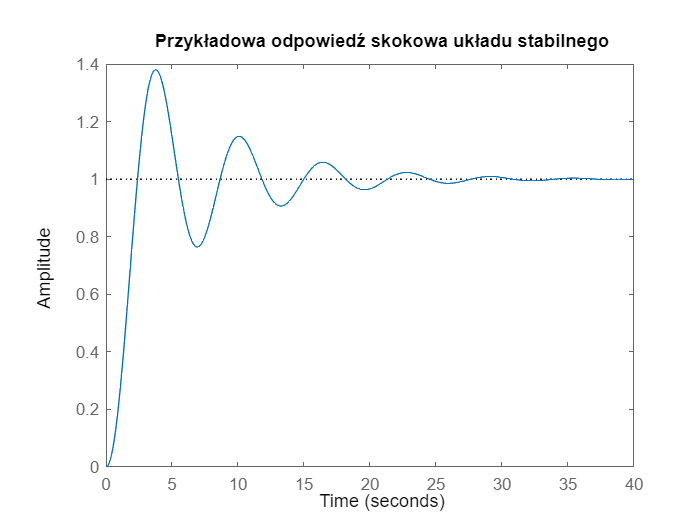

figure; step(G); title("Przykładowa odpowiedź skokowa układu stabilnego");

Sprawdzam za pomocą kryterium Hurwitza

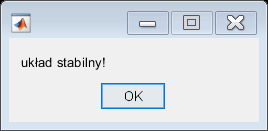

G = hurwitz(k, Ti, Td);

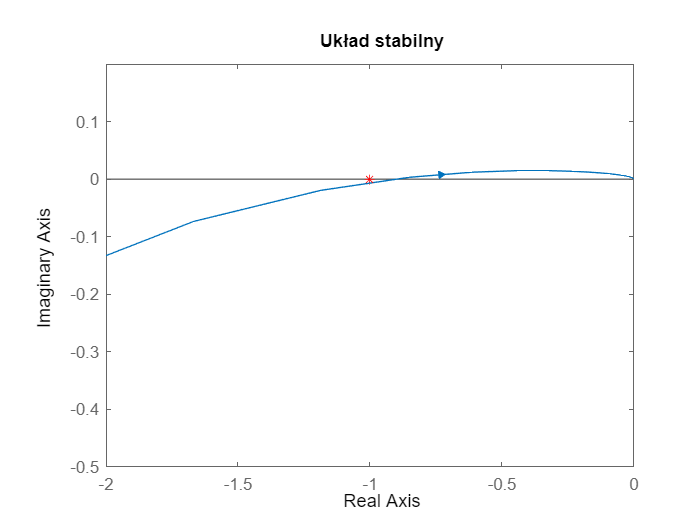

clear;

k = 2 ; Ti = 2.2 ; Td = 0.5;
G = nyquist_stab(k, Ti, Td);
axis([-2 0 -0.5 0.2]);
title("Układ stabilny");

Sprawdzam za pomocą kryterium Hurwitza

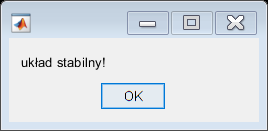

G = hurwitz(k, Ti, Td);

clear;

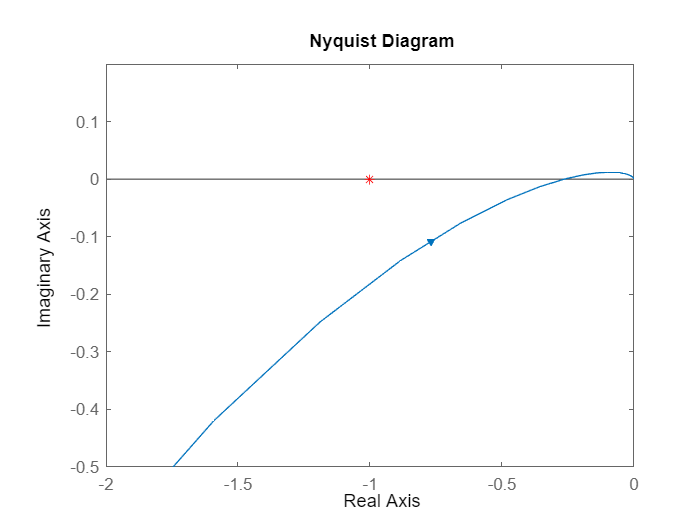

k = 2 ; Ti = 1 ; Td = 2;
G = nyquist_stab(k, Ti, Td);
axis([-2 0 -0.5 0.2]);

%title("Układ niestabilny");

Sprawdzam za pomocą kryterium Hurwitza

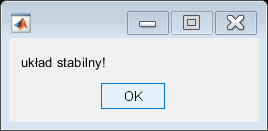

G = hurwitz(k, Ti, Td);

function [G_wy] = hurwitz(k, Ti, Td)
    T = 0.01;
    Go = tf([0 0 0 10], [1 2 2 1]);
    Gr = tf([k], [1]) + tf([0 k], [Ti 0]) + tf([Td*k 0], [T 1]);
    G = series(Go, Gr);
    Gz = feedback(G, 1);
    [~, mian_z] = tfdata(Gz);
    mian_z = mian_z{1};
    H = [[mian_z(2) mian_z(4) mian_z(6) 0]
         [mian_z(1) mian_z(3) mian_z(5) 0]
         [0  mian_z(2) mian_z(4) mian_z(6)]
         [0 mian_z(1) mian_z(3) mian_z(5)]];
    h1 = H(1, 1);
    h2 = det(H(1:2, 1:2));
    h3 = det(H(1:3, 1:3));
    h4 = det(H);

    if (h1 > 0) && (h2 > 0) && (h3 > 0) && (h4 > 0)
        msgbox("układ stabilny!");
    else
        msgbox("układ niestabilny!");
    end

    G_wy = Gz;
end

function [G_wy] = nyquist_stab(k, Ti, Td)
    T = 0.01;
    Go = tf([0 0 0 10], [1 2 2 1]);
    Gr = tf([k], [1]) + tf([0 k], [Ti 0]) + tf([Td*k 0], [T 1]);
    G = series(Go, Gr);
    figure; hold on;
    plotoptions = nyquistoptions('cstprefs');
    plotoptions.ShowFullContour = 'off';
    nyquist(G, plotoptions);
    plot(-1, 0, "xr"); hold("off");
    G_wy = feedback(G, 1);
end

**Wnioski**

Ćwiczenie pomogło zapoznać się ze sposobami badania stabilności - kryteriami Hurwitza i Nyquista. Dzięki niemu dowiedziałem się też jak dobierać parametry regulatora PID, aby dążyć do poprawy stabilności układu.